Load sample images

source_img = imread('03_sony_00005.JPG');
background_img = imread('03_sony_00001.JPG');
cur_img = im2gray(source_img);
bg_img = im2gray(background_img);

Create transformation:

take coordinates from imtool -> right click -> to workspace

imtool(cur_img)

coordinates = [1010 2719; 8324 2768; 8933 4878; 256 4657];
% according to real size of template rectangle
new_coordinates = [1 1; 3000*2.51 1; 3000*2.51 3000; 1 3000];
tform = fitgeotrans(coordinates, new_coordinates, 'projective')

tform =   projective2d with properties:

                 T: [3×3 double]
    Dimensionality: 2


new_img = imwarp(cur_img, tform);
croppedImg = imcrop(new_img, [3174.5 6805.5 7512 2999]);

imtool(croppedImg)

Background

back_img = imwarp(bg_img, tform);
bgImg = imcrop(back_img, [3174.5 6805.5 7512 2999]);
newBackImg = adapthisteq(bgImg);

Contrast

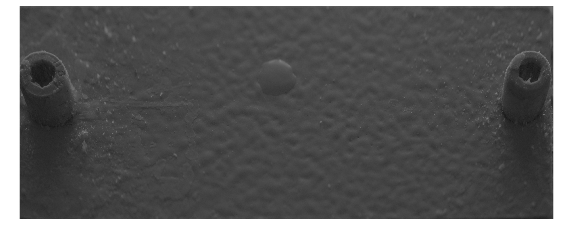

imshow(croppedImg)

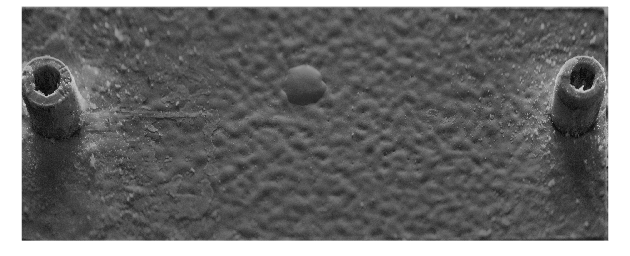

newContrastImg = adapthisteq(croppedImg);
imshow(newContrastImg)

Get image differense

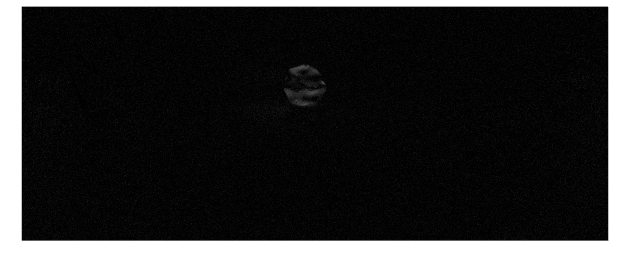

dif_img = imabsdiff(newContrastImg, newBackImg);
imshow(dif_img)

new_dif_img = wiener2(dif_img, [3 3]);

new_dif_img = 3000×7513 uint8 matrix
    1    1    1    1    1    2    2    2    1    1    1    1    1    1    2    2    2    3    5    5    2    1    1    1    1    1    1    2    2    2    2    2    3   10   14    1    2    2    1    1    2    2    3    3    2    2    1    1    1    2
    2    2    2    2    2    3    3    2    1    1    1    1    1    1    2    3    4    4    4    4    3    1    1    1    2    2    2    3    4    4    4    4    5    9   14    6    3    2    1    1    3    4    5    5    4    3    2    2    2    3
    2    2    1    1    1    2    2    2    1    1    1    1    1    1    2    4    4    4    3    3    3    2    2    1    1    1    2    3    4    4    5    6    5    6   11   11    2    3    2    3    3    4    6    6    6    4    3    2    2    3
    2    2    2    1    1    1    2    2    2    2    2    1    1    2    4    5    6    6    4    3    4    4    3    1    1    1    2    3    4    5    5    6    4    3    8   10    4    3    3    3    3    3

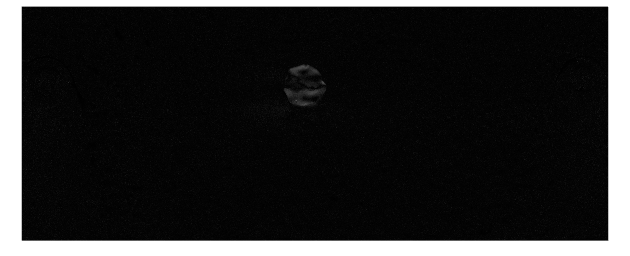

imshow(new_dif_img)

bw = edge(new_dif_img, 'log');